# Scent trails: tracking H₂S production with the MicroMap

## Author: Cyrille C. Thinnes, University of Galway

This case study presents a worked example of MicroMap applications. It introduces key concepts in microbiome metabolism and constraint-based modelling, serving as both an educational resource and an accessible entry point to the COBRA Toolbox [1]. You can find an [accompanying video walkthrough on YouTube](https://youtu.be/9N8fkNOSR5I). We recommend first completing the ‘*MicroMap exploration with CellDesigner*’ tutorial.

## Introduction

The most abundant gases contributing to flatulence are odourless, such as hydrogen (H₂), carbon dioxide (CO₂), and methane (CH₄) [2]. The odoriferous onus pertains to trace gases (<1% of total volume), notably sulphur-containing compounds, of which hydrogen sulphide (H₂S) has been identified to be the most putrid perpetrator [3]. H₂S is produced from microbiome metabolism and is linked to health and disease [4]. We shall use the MicroMap to gain mechanistic insights into the metabolism of this vicious volatile.

## MicroMap inspection with CellDesigner alone

First, we inspect the MicroMap in CellDesigner to gain preliminary mechanistic insights into microbial H₂S metabolism. Open the MicroMap and search for H₂S using Ctrl+F (Find Species). Enter the VMH abbreviation h2s, tick name (not ID), and choose ‘begin with’ to capture all compartments. Press ‘Show All’.CellDesigner will highlight all h2s occurrences with pink boxes. When zooming out, you will notice clusters of H₂S-associated reactions. To aid inspection, recolour these metabolites: with all selected, click ‘Change Color & Shape’, choose a bright red, enlarge the size (e.g. 200 × 75), and apply to all occurrences. All H₂S species are now easily spotted across the map.

Zooming out reveals that H₂S metabolites cluster in the top right quadrant. Since the MicroMap is organised by subsystem, we can now examine which reactions and pathways they belong to. Zooming into the ‘Sulfur Metabolism’ region shows two distinct H₂S nodes. Although some reactions are closely positioned and partially overlapping, they can be easily identified by selecting the reaction arrow and reading its name in the ‘Notes’ window. Reaction appearance can be edited via the ‘Change Color & Shape’ button (e.g. line width 5, red), and multiple reactions can be highlighted and edited simultaneously by holding ‘Shift’ while selecting them. We may also highlight reaction cascades by applying colour codes, e.g., by marking reactions directly connected to H₂S in red and those further up/downstream in orange (**Figure 1**).

We see two distinct sections (**Figure 1**), linked by a common node of sulphite (SO₃²⁻):

- Organic (left): H₂S is involved in the interconversion of carbon-containing compounds.

- Inorganic (right): H₂S is involved in the interconversion of sulphur-containing ions.

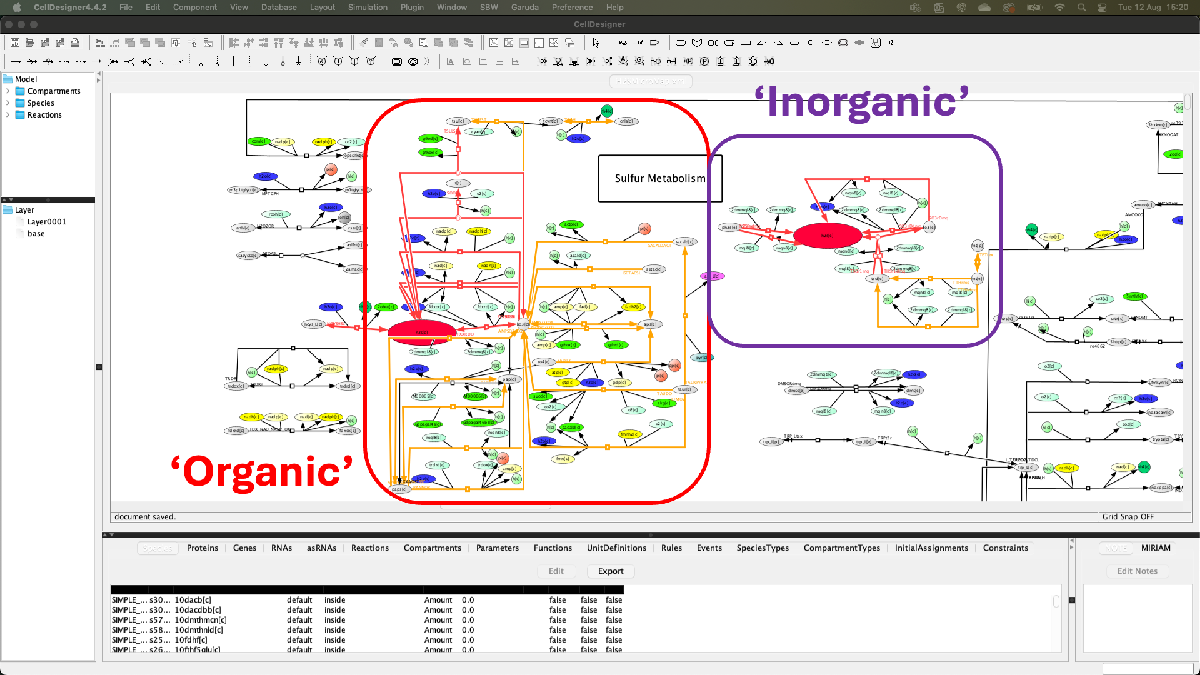

**Figure 1: **H₂S metabolism inspection using the MicroMap. The H₂S molecules were enlarged and highlighted in bright red to easily identify their location on the map. Reactions directly involving H₂S were then highlighted in red, with further up- and down-stream reactions in orange, to highlight the wider H₂S-involving network. This approach reveals an ‘organic’ reaction group primarily involving carbon-containing reaction partners, and an ‘inorganic’ reaction group primarily involving inorganic sulphur compounds.

Proceeding by inspecting the methionine, cysteine, and serine metabolism subsystems reveals recurring amino acid transformations involving H₂S, including between cysteine and pyruvate, cysteine and serine, homocysteine and cysteine, and acetylserine and cysteine.

In summary, inspection of the MicroMap alone reveals that H₂S is concentrated in the sulphur, methionine/cysteine, and serine metabolism subsystems. Multiple direct and indirect routes exist for H₂S formation, including amino acid transformations and sulphur anion conversions. Across these, the repeated H₂S ↔ SO₃²⁻ interconversion emerges as a central organising feature, linking organic and inorganic sulphur metabolism.

A quick way to assess whether a microbe partakes in H₂S metabolism is to load its reconstruction visualisation and highlight the H₂S molecules, as outlined above. If any highlighted H₂S metabolite is connected to a reconstruction reaction, the microbe can perform that reaction. For example, when comparing the pan-reconstruction visualisations of Desulfovibrio desulfuricans and Lactobacillus pasteurii ([downloaded from the Harvard Dataverse](https://dataverse.harvard.edu/dataset.xhtml?persistentId=doi:10.7910/DVN/ENQSOO)), the former shows extensive H₂S metabolism, whereas the latter shows none (**Figure 2**).

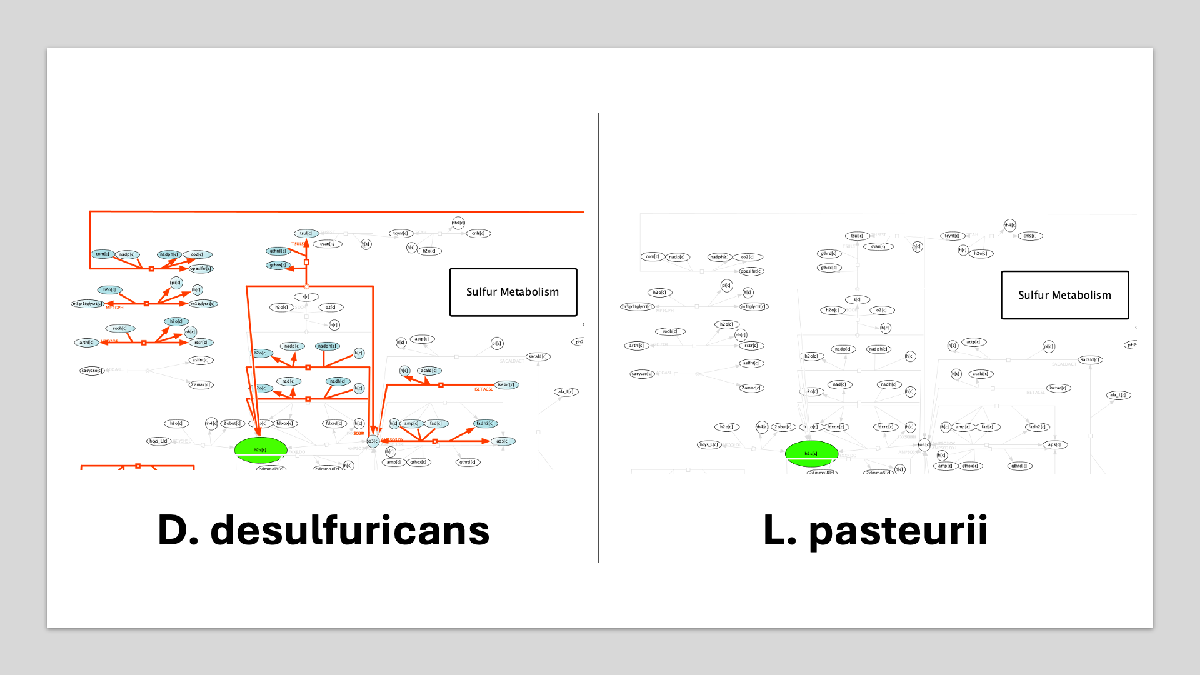

**Figure 2: **Comparison of H₂S metabolism in different reconstructions. Reactions involving H₂S can be identified by using the genome-scale metabolic reconstruction visualisation for a given microbe and highlighting all the contained H₂S metabolites. If H₂S is connected to an already coloured-in reaction, it will be a reaction partner.

## MicroMap integration with the COBRA Toolbox

### First steps

The next steps require a current version of the COBRA Toolbox.1 For installation instructions, please [follow the installation guide](https://opencobra.github.io/cobratoolbox/stable/installation.html). Additional information and user documentation are available on the [COBRA Toolbox website](https://opencobra.github.io/cobratoolbox/stable/index.html).

Download the MicroMap CellDesigner .xml file [from the Harvard Dataverse](https://dataverse.harvard.edu/dataset.xhtml?persistentId=doi:10.7910/DVN/FZKMJ8) and place it in your chosen MATLAB working directory.If required, initialise the COBRA Toolbox and set the solver.

%First Steps
initCobraToolbox(false); %no need to update if you have the latest version
changeCobraSolver('gurobi'); %set your installed solver

### Parsing the MicroMap into the COBRA Toolbox

CellDesigner .xml files can be parsed in the COBRA Toolbox with the *transformXML2Map* function. This splits the file into two components: the xml part (not relevant here) and the map part, which will be used in subsequent steps.

[xmlMicroMap, mapMicroMap] = transformXML2Map('MicroMap.xml');

The two parts can later be recombined into a CellDesigner .xml file using *transformMap2XML*:

transformMap2XML(xmlMicroMap, mapMicroMap, 'CopyMicroMap.xml');

### Modifying the MicroMap with the COBRA Toolbox

The MicroMap uses a coherent colour scheme to help recognise related metabolites. For some applications, however, it may be preferable to maximise contrast by simplifying the appearance. The *unifyMetabolicMapCD*function can be used to set all metabolite colours to white and all reaction colours to grey with a line width of 1 (**Figure 3**).

%Decolorise the map
mapMicroMapUnified = unifyMetabolicMapCD(mapMicroMap);
transformMap2XML(xmlMicroMap, mapMicroMapUnified, 'UnifiedMicroMap.xml');

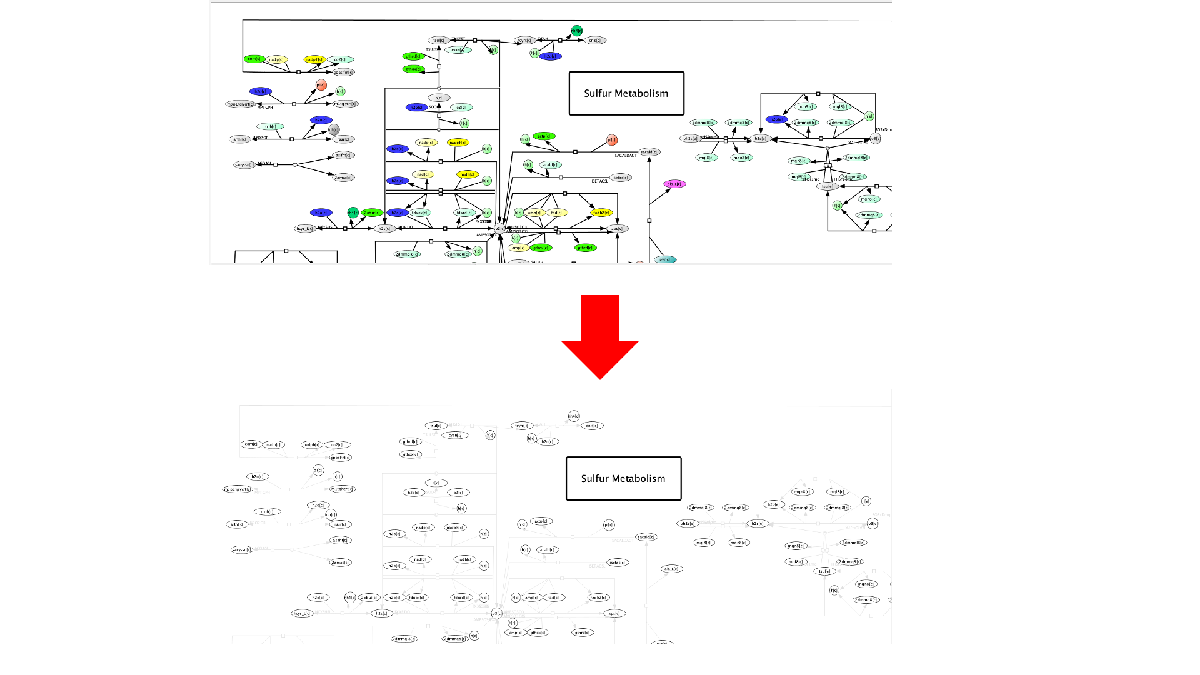

**Figure 3: **Decolorising the map. The COBRA Toolbox contains the unifyMetabolicMapCD function, which enables us to create a blank canvas from an already coloured map. All metabolite nodes will be set to white, and all reaction lines will be set to grey with line width 1.

The metabolic cartography suite includes several functions to adjust metabolite and reaction appearance. For our use case, we want to colour reactions involving H₂S, which can be done with *modifyReactionsMetabolites*. While the VMH identifier for H₂S (h2s[c]) is known, the associated reactions must first be identified. The Metabolic Cartography Tutorial Part 2 in the COBRA Toolbox demonstrates how to extract such a list from a genome-scale reconstruction using *findRxnsFromMets*. Here, however, we are working with large resources spanning many reconstructions. One option is to build a pan-reconstruction from all microbiome reconstructions; alternatively, the full set of VMH reactions can be queried by loading the database with *loadVMHDatabase*. With this in place, we can generate a list of reaction IDs that include h2s[c] as a reaction partner.

%Colouring metabolites and reactions.
%Identify all rxns containing h2s as a reaction partner from the VMH

%Load all reactions from the VMH Database
allVMH = loadVMHDatabase;
reactions = allVMH.reactions;

% Locate columns by header names
headers    = reactions(1,:);
colFormula = find(strcmpi(headers,'Formula'));
colRxnID   = find(strcmpi(headers,'ReactionID'));

% Data rows
data = reactions(2:end,:);

% Find reaction formulas containing h2s[c] (case-insensitive)
formulas = string(data(:, colFormula));
mask = contains(lower(formulas), "h2s[c]");

% Collect matching reaction IDs
H2Srxns = unique(string(data(mask, colRxnID)));

With the necessary inputs collected, we can now use *modifyReactionsMetabolites*. To define specific colours, we shall [employ html colour codes](https://htmlcolorcodes.com/color-names/). For using, e.g., a red-orange colour with line width of 10, we enter:

% Color in H2S reactions
mapMicroMapH2SRxns = modifyReactionsMetabolites(mapMicroMapUnified, ...
    H2Srxns , 'h2s[c]', 'ORANGERED', 10);
transformMap2XML(xmlMicroMap, mapMicroMapH2SRxns, 'H2SRxnsMicroMap.xml');

The resulting map highlights all reactions involving H₂S in microbiome metabolism, mirroring the manually generated CellDesigner map described above (**Figure 2**). Accordingly, the biochemical interpretation remains the same.

### Comparing the reaction content in different reconstructions

In the CellDesigner section above, we inspected pre-generated reconstruction visualisations by manually colouring H₂S metabolites to check their adjacency to reactions of interest (**Figure 2**). With the COBRA Toolbox, we can perform the same analysis from scratch, starting with the reconstructions and the MicroMap and using *visualizeReconstructionsOnMap*. Download the AGORA2 pan-species reconstructions (.mat format) for Desulfovibrio desulfuricans and Lactobacillus pasteurii [from the Harvard Dataverse](https://dataverse.harvard.edu/dataset.xhtml?persistentId=doi:10.7910/DVN/LAO2XM) (you can search with wildcards, e.g. *desulfuricans). Place the reconstructions in the same directory (not necessarily the working directory). For visualisation, run:

% Visualising reconstructions
visualizeReconstructionsOnMap('MicroMap.xml', pwd);

(assuming both the MicroMap and reconstructions are in your MATLAB working directory – you can also specify exact paths if needed.) Running the code will generate visualisations for each reconstruction: MicroMap_panDesulfovibrio_desulfuricans.xml and MicroMap_panLactobacillus_pasteurii.xml. Metabolite colours can be modified with *changeMetColor*, and node sizes with *changeNodesArea*. Remember to parse each map into MATLAB before making changes (see above). Thus, we can run:

%Parse both maps into Matlab
[xmlDDesu, mapDDesu] = transformXML2Map('MicroMap_panDesulfovibrio_desulfuricans.xml');
[xmlLPast, mapLPast] = transformXML2Map('MicroMap_panLactobacillus_pasteurii.xml');

%Change the colour for the h2s metabolites
mapDDesuH2S = changeMetColor(mapDDesu, {'h2s[c]'}, 'LIME');
mapLPastH2S = changeMetColor(mapLPast, {'h2s[c]'}, 'LIME');

%Change the node size for the h2s metabolites
mapDDesuH2S = changeNodesArea(mapDDesuH2S, {'h2s[c]'}, 75, 150);
mapLPastH2S   = changeNodesArea(mapLPastH2S, {'h2s[c]'}, 75, 150);

%Reconstitute into CellDesigner maps
transformMap2XML(xmlDDesu, mapDDesuH2S, 'MicroMap_H2SpanDesulfovibrio_desulfuricans.xml');
transformMap2XML(xmlLPast, mapLPastH2S, 'MicroMap_H2SpanLactobacillus_pasteurii.xml');

With this approach, it is straightforward to see which reconstructions contain reactions involving H₂S by checking whether a highlighted H₂S node is linked to a highlighted reconstruction reaction in CellDesigner. In this example, Desulfovibrio desulfuricans contains numerous H₂S-producing reactions, whereas Lactobacillus pasteurii contains none. Since H₂S is widespread across microbes, L. pasteurii is unusual. This raises the question: how does H₂S metabolism compare across different Lactobacillus species? We can generate a heatmap of reaction presence across reconstruction visualisations using *visualizeNormalizedRxnPresence*. First, download all Lactobacillus reconstructions from the Harvard Dataverse. (NB: if the MATLAB Parallel Computing Toolbox is not installed, we recommend downloading only a small subset, e.g. three reconstructions, as sequential computation time can otherwise be excessive.) For simplicity, create a new working directory and place the MicroMap and all pan-Lactobacillus reconstructions inside.

%First create the reconstructions visualisations
visualizeReconstructionsOnMap('MicroMap.xml', pwd);

%Then create a normalised rxn presence heatmap
visualizeNormalizedRxnPresence(pwd);

%Highlight h2s in the normalised reaction presence heatmap.
[xmlHeatmap, mapHeatmap] = ... 
    transformXML2Map('normalisedReactionHeatmap.xml');
mapHeatmap = changeMetColor(mapHeatmap, {'h2s[c]'}, 'LIME');
mapHeatmap = changeNodesArea(mapHeatmap, {'h2s[c]'}, 75, 150);

%Reconstitute the map
transformMap2XML(xmlHeatmap, ...
    mapHeatmap, 'H2SLactobacillusNormRxnHeatmap.xml')

From the heatmap, it is evident that H₂S-involving reactions are not ubiquitous across Lactobacillus species; most lack the capacity for H₂S metabolism (**Figure 4**). This highlights variability in microbial contributions to sulphur cycling in the gut, with Lactobacillus playing only a minimal role.

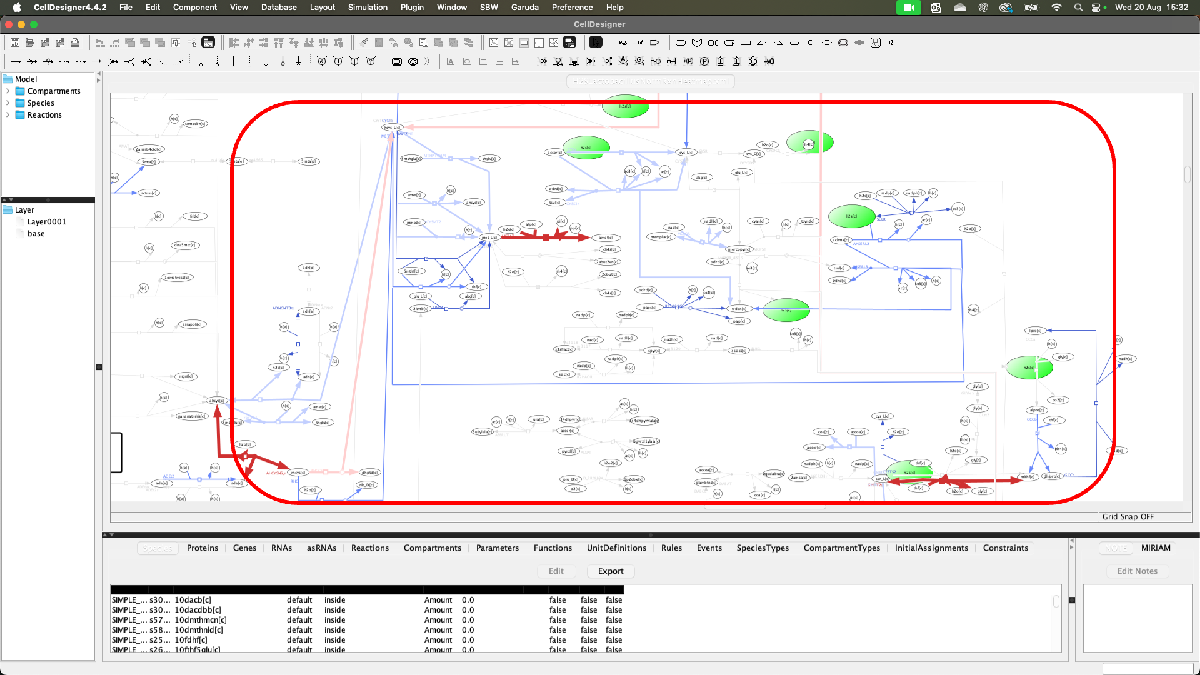

**Figure 4: **Heatmap of relative reaction abundance for all pan Lactobacillus species contained within AGORA2. The thin, dark blue lines indicate a reaction presence of <30%. The H₂S molecules are highlighted to facilitate inspecting which reactions are attached to H₂S and therefore engage in H₂S metabolism.

### Visualising flux results from flux balance analysis

The MicroMap enables visualisation of flux results from microbiome metabolic modelling. Flux balance analysis (FBA) can be used to estimate the maximum yields of key metabolites, such as H₂S in our case study. For a general introduction to FBA, we recommend first consulting the [introductory examples with the E. coli core model](https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorial_ecoliCoreModel_part1.html).

Let’s investigate H₂S secretion in Desulfovibrio desulfuricans, a microbe known to play a key role in hydrogen sulphide production.2 You can download the D. desulfuricans pan-species reconstruction [from the Harvard Dataverse](https://dataverse.harvard.edu/dataset.xhtml?persistentId=doi:10.7910/DVN/LAO2XM). Using FBA, we can simulate the maximum secretion of H₂S. To do this, we set the objective function to the H₂S exchange reaction and adjust its lower bound to 0, thereby preventing uptake of H₂S into the cell.

%Load the reconstruction of interest
dDesu = readCbModel('panDesulfovibrio_desulfuricans.mat');

%Load and decolorise the MicroMap, if not still loaded from previously
[xmlMicroMap, mapMicroMap] = transformXML2Map('MicroMap.xml');
mapMicroMapUnified = unifyMetabolicMapCD(mapMicroMap);

%Set the objective function to h2s secretion
dDesu = changeObjective(dDesu, 'EX_h2s(e)');
dDesu = changeRxnBounds(dDesu, 'EX_h2s(e)', 0, 'l');

In the downloaded reconstruction, exchange reaction bounds are virtually unrestricted. Modelling H₂S secretion from such an unlimited sulphur supply risks computational artefacts, where results reflect mathematical boundaries rather than biochemical mechanisms. To avoid this, we set uptake of major sulphur-containing compounds to physiologically more realistic levels by constraining the lower bounds of their exchange reactions to around –20 mmol·g⁻¹·DW⁻¹.

%Exchange reactions pertaining to most major sulphur-containing compounds
allS = {
    'EX_Lcyst(e)'
    'EX_butso3(e)'
    'EX_cgly(e)'
    'EX_cys_L(e)'
    'EX_ethso3(e)'
    'EX_glycys(e)'
    'EX_glymet(e)'
    'EX_h2s(e)'
    'EX_hexs(e)'
    'EX_isetac(e)'
    'EX_met_D(e)'
    'EX_met_L(e)'
    'EX_metala(e)'
    'EX_metsox_R_L(e)'
    'EX_metsox_S_L(e)'
    'EX_mops(e)'
    'EX_mso3(e)'
    'EX_so4(e)'
    'EX_sulfac(e)'
    'EX_taur(e)'
    'EX_tchola(e)'
    'EX_tdchola(e)'
    'EX_tdechola(e)'
    'EX_tsul(e)'
};

%Set the uptake rate for all major sulfur-containin compounds
dDesu = changeRxnBounds(dDesu, allS, -20, 'l');

We can then run FBA to estimate the maximum H₂S secretion under these conditions. The associated flux distribution can be visualised with the *addFluxFBA* function.

%Solve FBA and visualise the results
allSFBA = optimizeCbModel(dDesu);

mapAllSFBA = addFluxFBA(mapMicroMapUnified, dDesu, allSFBA, 'DARKVIOLET');
transformMap2XML(xmlMicroMap, mapAllSFBA, 'H2SMicroMapAllSFBA.xml');

We can compare results by running FBA under different conditions. From our earlier MicroMap inspection, H₂S production is linked to both inorganic sulphur compounds and sulphur-containing amino acids such as cysteine and methionine. Accordingly, we shall run FBA with uptake permitted primarily from inorganic compounds, and then from cysteine and methionine.

%Define list of inorganic sulphur-containing compounds
inorgs = {
    'EX_tsul(e)'
    'EX_so4(e)'
    }

%Define list of cysteine and methionine compounds
cysMets = {
    'EX_cgly(e)'
    'EX_cys_L(e)'
    'EX_glycys(e)'
    'EX_glymet(e)'
    'EX_met_D(e)'
    'EX_met_L(e)'
    'EX_metala(e)'
    }

%Set all uptake bounds for the major sulphur-containing compounds to 0
dDesu = changeRxnBounds(dDesu, allS, 0, 'l');

%Set the uptake rate for inorganic sulphur compounds
dDesu = changeRxnBounds(dDesu, inorgs, -20, 'l');

%Solve FBA and visualise the results
inorgsFBA = optimizeCbModel(dDesu);

mapInorgsFBA = addFluxFBA(mapMicroMapUnified, dDesu, inorgsFBA, 'DARKVIOLET');
transformMap2XML(xmlMicroMap, mapInorgsFBA, 'H2SMicroMapInorgsFBA.xml');

%Set the uptake rate for cysteine and methionine sulphur compounds
dDesu = changeRxnBounds(dDesu, inorgs, 0, 'l');
dDesu = changeRxnBounds(dDesu, cysMets, -20, 'l');

%Solve FBA and visualise the results
cysMetsFBA = optimizeCbModel(dDesu);

mapCysMetsFBA = addFluxFBA(mapMicroMapUnified, dDesu, cysMetsFBA, 'DARKVIOLET');
transformMap2XML(xmlMicroMap, mapCysMetsFBA, 'H2SMicroMapCysMetsFBA.xml');

Inspection of the flux vectors shows that H₂S secretion is higher on a cysteine–methionine medium (100 mmol·g⁻¹·DW⁻¹) than on an inorganic sulphur donor medium (60 mmol·g⁻¹·DW⁻¹). Other sulphur compounds also contribute, as indicated by the full donor set (200 mmol·g⁻¹·DW⁻¹) (**Figure 5**). Remember that, while the FBA-derived flux result is unique, the underlying flux distribution may not be, since the system of linear equations is underdetermined. Nonetheless, these distributions remain valuable for interpreting the systems context of the solution.

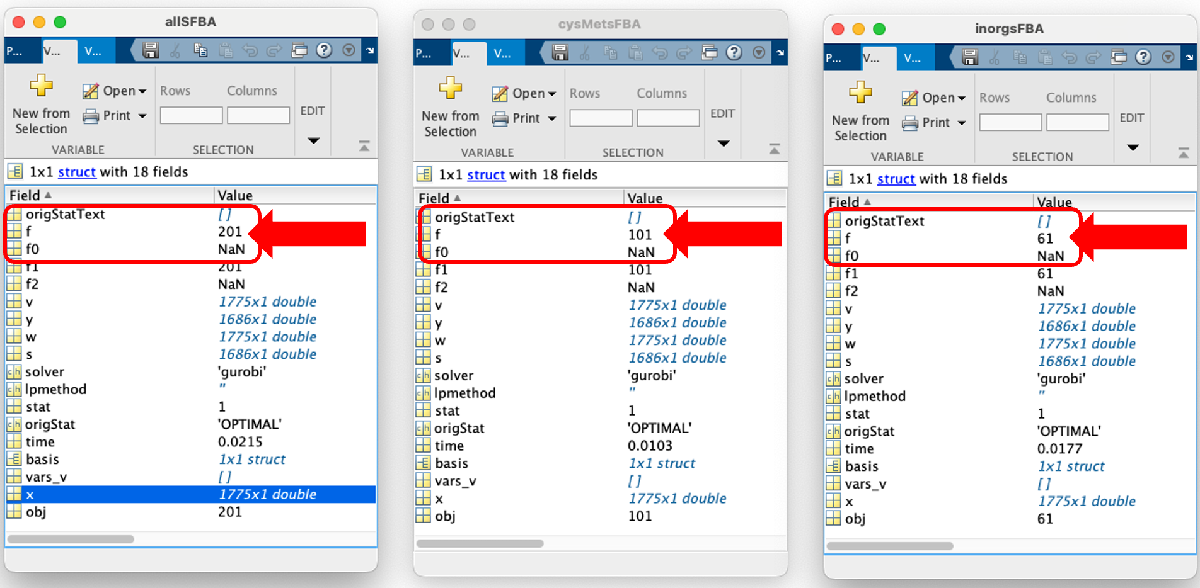

**Figure 5: **Comparison of FBA results obtained under different conditions. The allSFBA result allowed uptake from all major sulphur sources, cysMetsFBA allowed from cysteine and methionine, and inorgsFBA allowed from inorganic sulphur sources.

Note that all the solutions involve many different reactions across the MicroMap, well beyond sulphur metabolism. Comparing the results from the inorganics and cysMets FBA, we see that the cysMets solution does not carry flux in the region of the ‘Sulfur Metabolism’ biochemical subsystem, which highlights several reactions deriving from inorganic sulphur compounds (**Figure 6**).

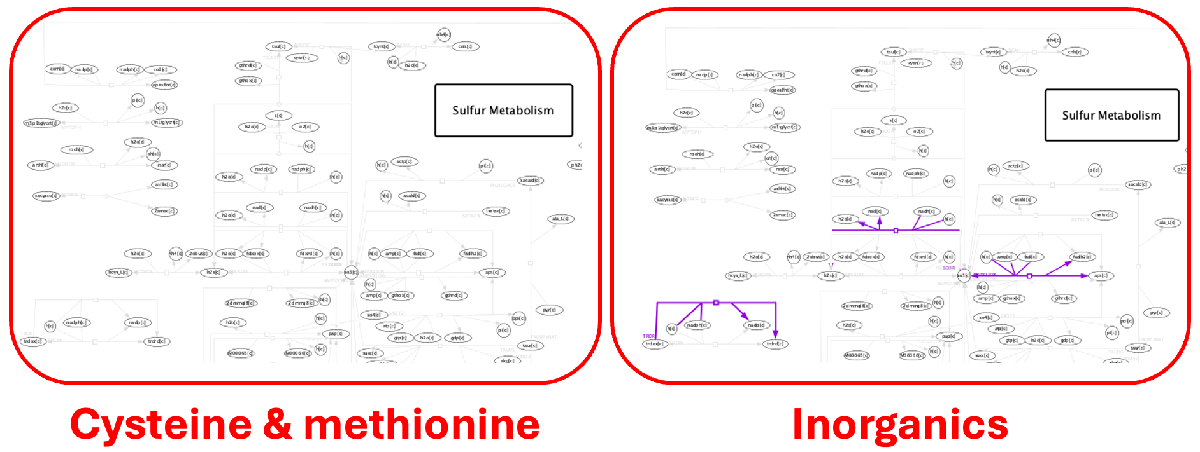

**Figure 6: **Comparison of flux distributions from FBA for maximising H2S secretion derived from using cysteine and methionine versus inorganic sulphur sources. No flux is observed in the ‘Sulfur Metabolism’ subsystem from a system of cysteine and methionine sulphur sources, whereas flux is observed from a system of inorganic sulphur sources.

Another interesting area is around the methionine subsystem, where the cysMets solution carries flux in more reactions. Upon closer inspection, one sees that the inorganics solution carries flux in reactions synthesising cysteine (**Figure 7**). The cysMets solution, does not carry flux in that same reaction to synthesise cysteine, but conversely, carries flux in reactions synthesising thiosulphate (**Figure 7**). This flux distribution highlights the interconnectedness and redundance for some metabolite syntheses.

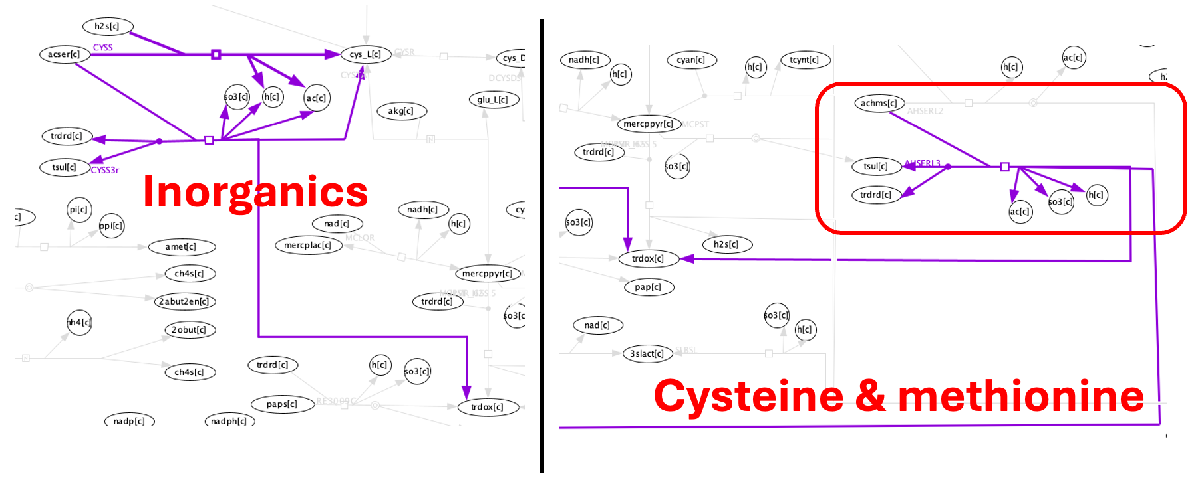

**Figure 7: **Comparison of flux distributions from FBA results for maximising H2S secretion derived from using cysteine and methionine versus inorganic sulphur sources. Cysteine can be produced from a system of inorganic sulphur sources, whereas thiosulphate can be produced from a system of cysteine and methionine sulphur sources.

In this case study, we have used the MicroMap to follow hydrogen sulphide metabolism step by step: first through manual inspection in CellDesigner, and then programmatically via the COBRA Toolbox. We learned that some microbes, such as Desulfovibrio desulfuricans, possess extensive capacity for H₂S production, while others, such as Lactobacillus species, contribute little. The MicroMap can be flexibly integrated into a wide range of workflows, and we encourage readers to adapt and extend these approaches to their own research questions.

## References

1.             Heirendt L, Arreckx S, Pfau T, Mendoza SN, Richelle A, Heinken A, et al. Creation and analysis of biochemical constraint-based models using the COBRA Toolbox v.3.0. Nat Protoc. 2019;14(3):639-702.

2.             Mutuyemungu E, Singh M, Liu S, Rose DJ. Intestinal gas production by the gut microbiota: A review. Journal of Functional Foods. 2023;100:105367.

3.             Suarez FL, Springfield J, Levitt MD. Identification of gases responsible for the odour of human flatus and evaluation of a device purported to reduce this odour. Gut. 1998;43(1):100-4.

4.             Kushkevych I, Dordević D, Kollar P, Vítězová M, Drago L. Hydrogen Sulfide as a Toxic Product in the Small–Large Intestine Axis and its Role in IBD Development. Journal of Clinical Medicine. 2019;8(7):1054.